# 1. Space-charge prefill test - MATLAB

Run spacecharge_prefill_test.ipynb first, then Run All here. This .m and its companion .mlx contain the same independent test. Lengths: mm. Input frequencies: GHz. Voltages: kV. Currents: A. No Python-calculated grid, charge harmonics or fields are loaded. Y0 in inputs.mat is already one-based.

test_directory=fileparts(mfilename('fullpath'));
if ~isfile(fullfile(test_directory,'spacecharge_prefill_test.m'))
    test_file=matlab.desktop.editor.getActiveFilename;
    test_directory=fileparts(test_file);
    if ~isfile(fullfile(test_directory,'spacecharge_prefill_test.m'))
        test_directory=fileparts(which('spacecharge_prefill_test.m'));
    end
end
input_file=fullfile(test_directory,'inputs.mat');
assert(isfile(input_file), ...
    'Cannot find inputs.mat at: %s\nRun spacecharge_prefill_test.ipynb first.',input_file);
load(input_file);
assert(Nt>=16 && Ns>=1 && Ns<Nt/2);
assert(rc~=0 && yd==0 && rm1>=0 && rm1<rm2 && rm2<=rc);
assert(factor>=0 && factorregion>=0 && fillfactor>=0 && DCSPfactor>=0);

## 2. Reference beam and grid - Original KLJCmainsv22.m lines 45-86

Constants and reference/grid arithmetic are copied exactly.

CALCULATE THE REFERENCE PAMAMETER

Nt = double(Nt)

Nt = 128


Iz0=1/2/pi*2*pi/Nt*sum(Izt(Y0)); % A, araverge emission current
I0=abs(Iz0);
U0=1/2/pi*2*pi/Nt*sum(Izt(Y0).*Ut(Y0))/Iz0;% kV, average emission voltage

% constant
c=299792458;  % m/s, light speed
etom=-1.7588E11;  % C/kg, charge to mass of electron
eta0=4E-7*pi*c; % ohm, wave impendance of TEM

esign=sign(-etom); % for negative charged paticles, esign=1; for postive charged particles, esign=-1
etom=abs(etom);

etom = double(etom);
c    = double(c);
U0   = double(U0);

s=(1-(1+etom/c/c*U0*1E3)^(-2))^(1/2); % ve0/c
vetoc=(1-(1+etom/c/c*Ut*1E3).^(-2)).^(1/2); % vet/c
vn1=0*vetoc;
vn1(Y0)=s./vetoc(Y0); % ve0/ve(t) at the entrance


w=2*pi*f*1E9;  % rad/s, angular frequency of operating
w0=2*pi*f0*1E9;  % rad/s, angular frequency of resonant
k0=w0/c/1000;   % 1/mm,  wave number at resonant freqency
Lsb=pi*ones(1,Nc); % phaseshift beta0*Ls from the entrance of output cavity at resonant freqency

gama=1+etom*U0*1000/c/c; % Lorentz factor
betae=w/c/s/1000;  % 1/mm, betae at operating freqency

Nz = double(Nz);
dz=2*pi/betae/Nz;  % mm,

dz=L/floor(L/dz); % mm, increment of z
dz = double(dz);
zi=(z0:dz:z0+L)'; % mm, z position sequence

rcvs=interp1(rcv(1,:),rcv(2,:)*rc,zi,'linear','extrap'); % mm, tunnel radius sequence
assert(all(abs(rcvs-rc)<=1e-12),'This prefill test uses a constant tunnel radius.');

% Original line 89: only the source count is needed; Nesz is not used here.
    dN=floor(factorregion*rc/2.40483/dz); % N dz interval is included to calculate the local SP

## 3. Normalized coordinates, beam harmonics and wp - Original lines 132-159

Cavity field processing is not needed for these initial quantities.

z=betae*zi; % normalized z position
dt=betae*dz; % normalized time step & normalized position step, in real time step=position step/injecting velocity of electron


Iz=zeros(length(z),Ns);
QQ=zeros(length(z),Ns);

% intial value given
Y=Y0;
IzDC=1/2/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0)*ones(length(z),1); % normalized DC current along the axis
for k=1:Ns
    Iz(:,k)=1i/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0.*exp(-k*1i*tn1(Y)))*ones(length(z),1); % normalized,intial modulated current of 1st harmonic
end

QQDC=1/2/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0.*vn1(Y))*ones(length(z),1); % DC charge density along axis
for k=1:Ns
    QQ(:,k)=1i/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0.*exp(-k*1i*tn1(Y)).*vn1(Y))*ones(length(z),1); % normalized,intial modulated charged density
end

if rc~=0
    wp=factor*sqrt(I0*etom/pi/((rm2*1E-3)^2-(rm1*1E-3)^2)/(1/c/eta0)/c/s); % rad/s, plasma angular frquency
else
    
end

effe=0*ones(length(z),1); % if all electron reflected, the efficiency will be 100%
vez=1*ones(length(z),1); % ve/ve0
gamaz=(1-(vez*s).^2).^(-1/2);

## 4. Fixed upstream prefill - Original lines 161-179

Numerical formulas, five Bessel roots, and conditional gates are unchanged. TEST EXECUTION ADAPTER: parfor becomes for; no parallel pool is required. Known original edge case: for dN=1, sum(...) reduces across the harmonic row instead of source rows. This is intentionally not corrected here. With the modulated preset and factorregion=0.2, the checks detect it.

TEST DIAGNOSTICS FOR DISABLED PREFILL ONLY: Python retains zp/gamazp/QQfill when a gate is zero; original MATLAB does not create them in that branch. Repeat the original source-array formulas here solely to inspect/compare their geometry and phases. Esz00 is still zero. This does not claim that the original solver returns these disabled arrays.

if factor==0 || fillfactor==0 || DCSPfactor==0
    zp=repmat([z(1)-betae*dz:-betae*dz:z(1)-betae*dz*dN].',1,Ns+1);
    [Nfill,~]=size(zp);
    gamazp=[ones(Nfill,1),repmat(gamaz(1),Nfill,Ns)];
    QQfill=[repmat(QQDC(1),Nfill,1) repmat(QQ(1,:),Nfill,1).*exp(-1i*repmat([1:Ns],Nfill,1).*(z(1)-zp(:,2:end)))];
end

% Now we compute a prefill space charge
Esz00=zeros(length(z),1+Ns);

if factor~=0 && fillfactor~=0 && DCSPfactor~=0
    % For DC beam filled ahead of the entrance
    zp=repmat([z(1)-betae*dz:-betae*dz:z(1)-betae*dz*dN].',1,Ns+1);
    [Nfill,~]=size(zp);
    gamazp=[ones(Nfill,1),repmat(gamaz(1),Nfill,Ns)];
    QQfill=[repmat(QQDC(1),Nfill,1) repmat(QQ(1,:),Nfill,1).*exp(-1i*repmat([1:Ns],Nfill,1).*(z(1)-zp(:,2:end)))];
    if rc~=0  % for cylindrical beam
        for kk=1:length(z)
            Esz00(kk,:)=esign*dz*betae*sum(-QQfill.*sign(z(kk)-zp)/2*wp^2/w^2*(gama+1)/gama/gama.*(exp(-2.40483*gamazp.*abs(zp-z(kk))/betae/rc)/(rm2^2-rm1^2)*(2/2.40483*(rm2*besselj(1,2.40483*rm2/rc)-rm1*besselj(1,2.40483*rm1/rc))/besselj(1,2.40483))^2+exp(-5.52008*gamazp.*abs(zp-z(kk))/betae/rc)/(rm2^2-rm1^2)*(2/5.52008*(rm2*besselj(1,5.52008*rm2/rc)-rm1*besselj(1,5.52008*rm1/rc))/besselj(1,5.52008))^2+exp(-8.65373*gamazp.*abs(zp-z(kk))/betae/rc)/(rm2^2-rm1^2)*(2/8.65373*(rm2*besselj(1,8.65373*rm2/rc)-rm1*besselj(1,8.65373*rm1/rc))/besselj(1,8.65373))^2+exp(-11.79153*gamazp.*abs(zp-z(kk))/betae/rc)/(rm2^2-rm1^2)*(2/11.79153*(rm2*besselj(1,11.79153*rm2/rc)-rm1*besselj(1,11.79153*rm1/rc))/besselj(1,11.79153))^2+exp(-14.93092*gamazp.*abs(zp-z(kk))/betae/rc)/(rm2^2-rm1^2)*(2/14.93092*(rm2*besselj(1,14.93092*rm2/rc)-rm1*besselj(1,14.93092*rm1/rc))/besselj(1,14.93092))^2));
        end
        
    else   % for sheet beam

    end
    
end

## 5. Inspect the calculated prefill

Esz00 is dimensionless, not V/m. It is only the upstream contribution. factor multiplies wp, so the field scales as factor^2. Nonzero fillfactor/DCSPfactor only enable this calculation. Their numerical weighting of the combined space-charge field happens later, outside this test.

zp_mm=zp(:,1)/betae;
harmonics=0:Ns;
prefill_enabled=factor~=0 && fillfactor~=0 && DCSPfactor~=0;
fprintf('Case: %s; prefill enabled: %d; sources=%d; targets=%d; harmonics=0..%d\n', ...
    case_name,prefill_enabled,Nfill,length(z),Ns);

Case: uniform; prefill enabled: 1; sources=52; targets=3806; harmonics=0..8


Variable={'I0';'U0';'s';'wp';'wp/(2*pi)';'wp/w';'factor';'fillfactor';'DCSPfactor';'Nfill';'dN*dz';'dz';'dt'};
Value=[I0;U0;s;wp;wp/(2*pi);wp/w;factor;fillfactor;DCSPfactor;Nfill;dN*dz;dz;dt];
Unit={'A';'kV';'1';'rad/s';'Hz';'1';'1';'1';'1';'sources';'mm';'mm';'1'};
disp(table(Variable,Value,Unit));

       Variable         Value          Unit    
    ______________    __________    ___________

    {'I0'        }            16    {'A'      }
    {'U0'        }           180    {'kV'     }
    {'s'         }       0.67315    {'1'      }
    {'wp'        }    3.7317e+09    {'rad/s'  }
    {'wp/(2*pi)' }    5.9391e+08    {'Hz'     }
    {'wp/w'      }       0.59391    {'1'      }
    {'factor'    }             1    {'1'      }
    {'fillfactor'}             1    {'1'      }
    {'DCSPfactor'}             1    {'1'      }
    {'Nfill'     }            52    {'sources'}
    {'dN*dz'     }        40.999    {'mm'     }
    {'dz'        }       0.78844    {'mm'     }
    {'dt'        }      0.024548    {'1'      }



style_axes=@(fig) set(findall(fig,'Type','axes'), ...
    'XGrid','on','YGrid','on','GridLineStyle','--', ...
    'GridColor',[0.5 0.5 0.5],'GridAlpha',0.45);
zoom_length=max(Nfill*dz,4*rc);

## 6. Normal grid and separate upstream sources

zp rows are stored nearest to farthest upstream; zp/betae is in mm. First source: zi(1)-dz. There is no source at the entrance itself.

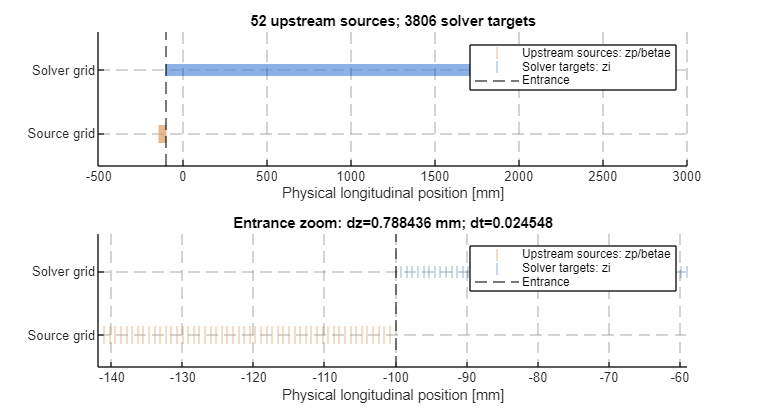

figure('Name','Prefill and solver grids','Position',[100 100 1100 600]);
tiledlayout(2,1);
for panel=1:2
    nexttile; hold on;
    plot(zp_mm,zeros(Nfill,1),'|','MarkerSize',12,'Color',[0.85 0.45 0.1], ...
        'DisplayName','Upstream sources: zp/betae');
    plot(zi,ones(length(zi),1),'|','MarkerSize',8,'Color',[0.1 0.4 0.8], ...
        'DisplayName','Solver targets: zi');
    xline(zi(1),'k--','DisplayName','Entrance');
    yticks([0 1]); yticklabels({'Source grid','Solver grid'}); ylim([-0.5 1.6]);
    xlabel('Physical longitudinal position [mm]'); legend('Location','northeast');
    if panel==1
        title(sprintf('%d upstream sources; %d solver targets',Nfill,length(z)));
    else
        xlim([zi(1)-zoom_length-dz,min(zi(end),zi(1)+zoom_length)]);
        title(sprintf('Entrance zoom: dz=%.6g mm; dt=%.6g',dz,dt));
    end
end
style_axes(gcf);

## 7. Upstream charge and DC/RF kernel factors

QQfill(:,1)=QQDC(1); RF columns rotate by exp(-i*k*(z(1)-zp)). gamazp is 1 for DC, but gamaz(1) for RF harmonics. If a gate is zero, these arrays are diagnostics only.

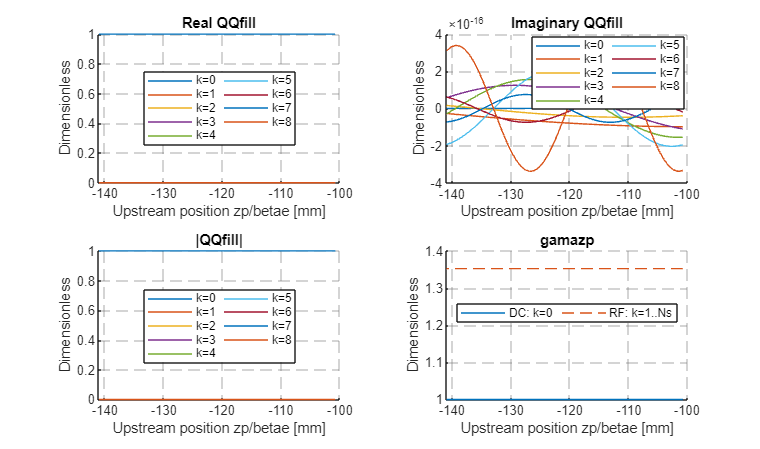

figure('Name','Prefill source harmonics','Position',[100 100 1100 650]);
tiledlayout(2,2);
for panel=1:4
    nexttile; hold on;
    if Nfill>0
        if panel==4
            plot(zp_mm,gamazp(:,1),'DisplayName','DC: k=0');
            plot(zp_mm,gamazp(:,2),'--','DisplayName','RF: k=1..Ns');
        else
            for k=0:Ns
                if panel==1
                    values=real(QQfill(:,k+1));
                elseif panel==2
                    values=imag(QQfill(:,k+1));
                else
                    values=abs(QQfill(:,k+1));
                end
                plot(zp_mm,values,'DisplayName',sprintf('k=%d',k));
            end
        end
        legend('Location','best','NumColumns',2);
    else
        text(0.5,0.5,'No upstream sources (dN=0)','Units','normalized','HorizontalAlignment','center');
    end
    labels={'Real QQfill','Imaginary QQfill','|QQfill|','gamazp'};
    title(labels{panel}); xlabel('Upstream position zp/betae [mm]'); ylabel('Dimensionless');
end
style_axes(gcf);

## 8. Prefill field on the normal solver grid

DC is negative with the electron-beam convention and decays downstream. Uniform entrance current has RF coefficients only at roundoff level.

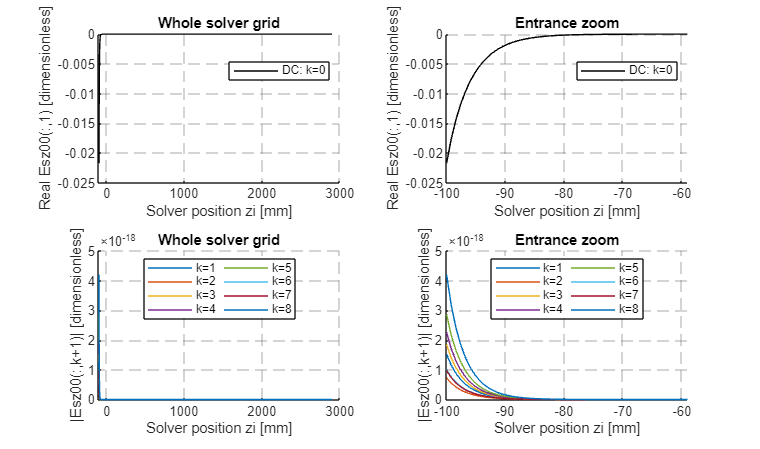

figure('Name','Prefill field profiles','Position',[100 100 1100 650]);
tiledlayout(2,2);
for panel=1:4
    nexttile; hold on;
    if panel<=2
        plot(zi,real(Esz00(:,1)),'k','DisplayName','DC: k=0');
        ylabel('Real Esz00(:,1) [dimensionless]');
    else
        for k=1:Ns
            plot(zi,abs(Esz00(:,k+1)),'DisplayName',sprintf('k=%d',k));
        end
        ylabel('|Esz00(:,k+1)| [dimensionless]');
    end
    if mod(panel,2)==0
        xlim([zi(1),min(zi(end),zi(1)+zoom_length)]); title('Entrance zoom');
    else
        title('Whole solver grid');
    end
    xlabel('Solver position zi [mm]'); legend('Location','best','NumColumns',2);
end
style_axes(gcf);

disp(table(harmonics.',Esz00(1,:).',max(abs(Esz00),[],1).', ...
    'VariableNames',{'Harmonic','Esz00_at_entrance','Maximum_magnitude'}));

    Harmonic       Esz00_at_entrance       Maximum_magnitude
    ________    _______________________    _________________

       0          -0.021745+0i                  0.021745    
       1         1.8188e-19+1.5124e-18i       1.5233e-18    
       2        -3.0845e-19+6.5867e-19i       7.2731e-19    
       3         1.2083e-18+1.4031e-18i       1.8517e-18    
       4         4.5725e-19+2.2091e-18i       2.2559e-18    
       5          2.359e-19+2.8555e-18i       2.8652e-18    
       6         9.9621e-19-1.6584e-19i       1.0099e-18    
       7        -7.8409e-19-5.6917e-19i       9.6889e-19    
       8         1.5066e-18+3.9231e-18i       4.2025e-18    



## 9. Complex RF coefficient and reconstructed field

k is the physical harmonic; MATLAB column k+1 includes the preceding DC. E(theta)=real(E0)+imag(sum(Ek*exp(i*k*theta))). This is the unweighted prefill contribution, not the total electric field.

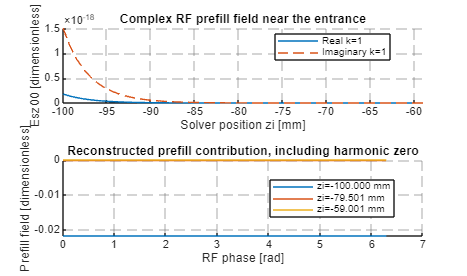

k=1;
figure('Name','Complex and reconstructed prefill','Position',[100 100 1100 650]);
tiledlayout(2,1);
nexttile; hold on;
plot(zi,real(Esz00(:,k+1)),'DisplayName',sprintf('Real k=%d',k));
plot(zi,imag(Esz00(:,k+1)),'--','DisplayName',sprintf('Imaginary k=%d',k));
xlim([zi(1),min(zi(end),zi(1)+zoom_length)]);
xlabel('Solver position zi [mm]'); ylabel('Esz00 [dimensionless]');
title('Complex RF prefill field near the entrance'); legend('Location','best');
nexttile; hold on;
theta=linspace(0,2*pi,500).';
phase=exp(1i*theta*(1:Ns));
z_indices=unique([1,min(floor(Nfill/2)+1,length(z)),min(Nfill+1,length(z))]);
for kz=z_indices
    waveform=real(Esz00(kz,1))+imag(phase*Esz00(kz,2:end).');
    plot(theta,waveform,'DisplayName',sprintf('zi=%.3f mm',zi(kz)));
end
xlabel('RF phase [rad]'); ylabel('Prefill field [dimensionless]');
title('Reconstructed prefill contribution, including harmonic zero');
legend('Location','best'); style_axes(gcf);

## 10. Basic MATLAB consistency checks

These checks do not load Python results.

assert(Nfill==dN);
assert(isequal(size(zp),[Nfill,Ns+1]) && isequal(size(gamazp),size(zp)));
assert(isequal(size(QQfill),size(zp)) && isequal(size(Esz00),[length(z),Ns+1]));
assert(isfinite(wp));
assert(all(isfinite(zp),'all') && all(isfinite(gamazp),'all'));
assert(all(isfinite(QQfill),'all') && all(isfinite(Esz00),'all'));
expected_zp=repmat(z(1)-dt*(1:Nfill).',1,Ns+1);
assert(all(abs(zp-expected_zp)<=1e-12+1e-10*abs(expected_zp),'all'));
assert(all(abs(gamazp(:,1)-1)<=1e-12));
assert(all(abs(gamazp(:,2:end)-gamaz(1))<=1e-12+1e-10*abs(gamaz(1)),'all'));
assert(all(abs(QQfill(:,1)-QQDC(1))<=1e-12+1e-10*abs(QQDC(1))));
expected_QQfill=QQ(1,:).*exp(-1i*(1:Ns).*(z(1)-zp(:,2:end)));
assert(all(abs(QQfill(:,2:end)-expected_QQfill)<=1e-12+1e-10*abs(expected_QQfill),'all'));
if Nfill>0
    assert(abs(zp_mm(1)-(zi(1)-dz))<=1e-12+1e-10*abs(zi(1)-dz));
    assert(all(abs(diff(zp_mm)+dz)<=1e-12+1e-10*abs(dz)));
    assert(all(zp_mm<zi(1)));
end
assert(all(abs(imag(Esz00(:,1)))<=1e-12), ...
    'DC prefill must be real. For dN=1, see the original MATLAB sum-dimension issue in test/README.md.');
if ~prefill_enabled || Nfill==0
    assert(all(Esz00==0,'all'));
else
    assert(wp>0 && real(Esz00(1,1))<0);
    assert(all(real(Esz00(:,1))<=1e-12));
    assert(all(diff(real(Esz00(:,1)))>=-1e-12));
end
disp('PASS: MATLAB prefill geometry, phase, kernel and field checks.');

PASS: MATLAB prefill geometry, phase, kernel and field checks.


## 11. Export MATLAB results

Twenty-three calculated quantities, six test settings, and the case label. Complex matrices and empty source-matrix dimensions are preserved. Only this test's matlab_results.mat is overwritten; save -v7 for SciPy.

save(fullfile(test_directory,'matlab_results.mat'), ...
    'Iz0','I0','U0','s','vetoc','vn1','gama', ...
    'w','betae','dz','zi','z','dt','dN', ...
    'QQDC','QQ','gamaz','wp','zp','gamazp','QQfill','Esz00','Nfill', ...
    'Nt','Ns','factor','factorregion','fillfactor','DCSPfactor','case_name','-v7');
fprintf('Saved: %s\n',fullfile(test_directory,'matlab_results.mat'));

Saved: C:\Users\lsito\Desktop\PyKlyC\pyKlyC\test\4.spacecharge_prefll_test\matlab_results.mat


disp('Next: run compare_results.ipynb.');

Next: run compare_results.ipynb.
